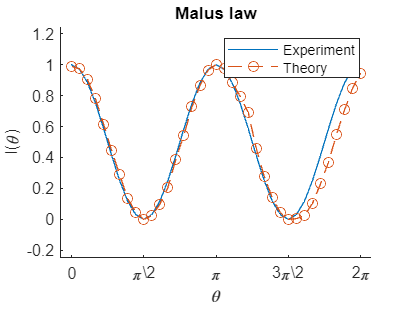

clear all
clc;

fileName="C:\Users\sanjo\OneDrive\Documentos\5_Semestre\Optics\Práctica 3.xlsx";
fileData = [];
% Specify the Excel file name
excelFileName = fileName;
% Read data from the Excel file
[numData, textData, rawData] = xlsread(excelFileName);

theta=linspace(0,2*pi,37);

hold on 
plot(theta,cos(theta).^2)
plot(theta,numData(1:37,6),'--o')

title('Malus law');
ylabel('I(\theta)');
xlabel('\theta');
legend("Experiment","Theory")
xlim([-0.25 6.53])
ylim([-0.25 1.25])
xticks([0 pi/2 pi 3*pi/2 2*pi])
xticklabels({'0',"\pi\2",'\pi',"3\pi\2",'2\pi'})


hold off

N=37;
theta=linspace(0,2*pi,N);
ECM=zeros(1,N);
Y_r=cos(theta).^2;
Y_t=numData(1:N,6)';

for i=1:N
    ECM(1,i)=(Y_r(1,i)-Y_t(1,i))^2;
end

V=1/N*(sum(ECM)) %Varianza inexplicada

V = 0.0062


D=sqrt(V) %Error cuadratico medio 

D = 0.0785